# Test the Model

## Read in optimised hyperparameters

LSTMCNN

optVars = load("HyperParameterSearch\OptVars\LSTMCNNoptVars.mat").optVars;
miniBatchSize = optVars.miniBatchSize;
learningrate = optVars.learningrate;
numLSTMBlocks = optVars.numLSTMBlocks;
numHiddenUnits = optVars.numHiddenUnits;
numCNNBlocks = optVars.numCNNBlocks;
filterSize = optVars.filterSize;
numFilters = optVars.numFilters;

LSTM

optVars = load("HyperParameterSearch\OptVars\LSTMoptVars.mat").optVars;
miniBatchSize = optVars.miniBatchSize;
learningrate = optVars.learningrate;
numFeatures = 3;
numBlocks = optVars.numBlocks;
numHiddenUnits = optVars.numHiddenUnits;
numResponse = 3;

## Test the model several times

rng(1);
numTesting = 10;
Maxepochs = 30;

LSTMCNN

modelName = 'LSTMCNN';
accuracy = {};
confusionmats = {};
for i = 1:numTesting
    % load data set
    XTrain = load(['DataSet\Test\Train\XTestTrain' num2str(i) '.mat']).XTestTrain;
    YTrain = load(['DataSet\Test\Train\YTestTrain' num2str(i) '.mat']).YTestTrain;
    XTest = load(['DataSet\Test\Test\XTestTest' num2str(i) '.mat']).XTestTest;
    YTest = load(['DataSet\Test\Test\YTestTest' num2str(i) '.mat']).YTestTest;    
    % model
    numResponse = numel(categories(YTest{1}));
    numFeatures = size(XTrain{1},1);
    layers = constructLSTMCNN(numFeatures,numLSTMBlocks,numHiddenUnits, ...
        numCNNBlocks,filterSize,numFilters,numResponse,false); 
    % train
    options = trainingOptions('adam', ...
        'MaxEpochs',Maxepochs, ...
        'MiniBatchSize',miniBatchSize, ...
        'InitialLearnRate',learningrate, ...
        'LearnRateDropPeriod',10, ...
        'LearnRateDropFactor',0.75, ...
        'LearnRateSchedule','piecewise', ...
        'Plots','none',...
        'GradientThreshold',1, ...
        'shuffle','every-epoch',...
        'Verbose',0,...
        'DispatchInBackground',true);
    net = trainNetwork(XTrain,YTrain,layers,options);
    % evaluate
    YPred = classify(net, XTest, "MiniBatchSize",miniBatchSize);
    valError = 0;
    for k = 1:length(YPred)
    valError = valError + mean(YPred{k} == YTest{k});
    end
    accuracy{end+1} = valError/length(YPred);
    TY = [];
    Y = [];
    YTest = YTest.';
    for k = 1:numel(YTest)
        TY = [TY;YTest{k}];
        Y = [Y;YPred{k}];
    end
    confusionMat = confusionmat(TY(:),Y(:));
    confusionmats{end+1} = confusionMat;
end

result = table(accuracy, confusionmats);
save(['Test\Results\' modelName 'result.mat'],'result','-mat');

LSTM

modelName = 'LSTM';
accuracy = {};
confusionmats = {};
pred = {};
for i = 1:numTesting
    % load data set
    XTrain = load(['DataSet\Test\Train\XTestTrain' num2str(i) '.mat']).XTestTrain;
    YTrain = load(['DataSet\Test\Train\YTestTrain' num2str(i) '.mat']).YTestTrain;
    XTest = load(['DataSet\Test\Test\XTestTest' num2str(i) '.mat']).XTestTest;
    YTest = load(['DataSet\Test\Test\YTestTest' num2str(i) '.mat']).YTestTest;    
    % model
    layers = constructLSTM(numFeatures,numBlocks,numHiddenUnits,numResponse,false); 

    options = trainingOptions('adam', ...
        'MaxEpochs',30, ...
        'MiniBatchSize',miniBatchSize, ...
        'InitialLearnRate',learningrate, ...
        'LearnRateDropPeriod',10, ...
        'LearnRateDropFactor',0.75, ...
        'LearnRateSchedule','piecewise', ...
        'Plots','none',...
        'GradientThreshold',1, ...
        'shuffle','every-epoch',...
        'Verbose',0,...
        'DispatchInBackground',true);
    net = trainNetwork(XTrain,YTrain,layers,options);
    % evaluate
    YPred = classify(net, XTest, "MiniBatchSize",miniBatchSize);
    valError = 0;
    for k = 1:length(YPred)
        valError = valError + mean(YPred{k} == YTest{k});
    end
    accuracy{end+1} = valError/length(YPred);
    TY = [];
    Y = [];
    YTest = YTest.';
    for k = 1:numel(YTest)
        TY = [TY;YTest{k}];
        Y = [Y;YPred{k}];
    end
    confusionMat = confusionmat(TY(:),Y(:));
    pred{end+1} = YPred; 
    confusionmats{end+1} = confusionMat;
end
result = table(accuracy, confusionmats);
save(['Test\Results\' modelName 'result.mat'],'result','-mat');
save(['Test\Results\' modelName 'pred.mat'],'pred','-mat');

## Standard deviation of accuracy

modelName = 'LSTM';
accuracyList = [];
accuracy = load(['Test\Results\' modelName 'result.mat']).result.accuracy;
for i = 1:numTesting
    accuracyList = [accuracyList, accuracy{i}];
end
accuracyMean = mean(accuracyList)

accuracyMean = 0.9432

accuracyStd = std(accuracyList)

accuracyStd = 0.0027

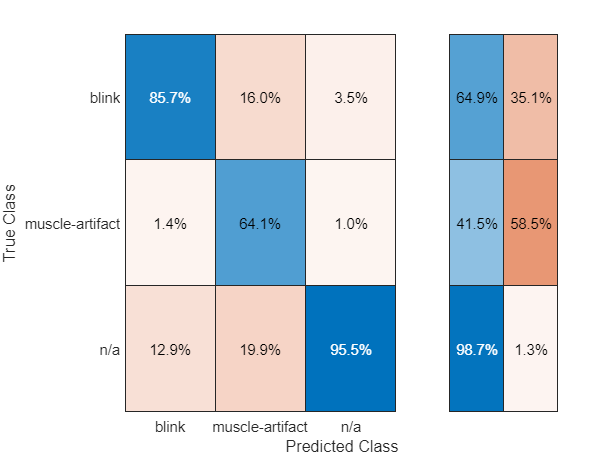

figure;
confusionchart(load('Test\Results\LSTMresult.mat').result.confusionmats{1}, ...
    {'blink' 'n/a' 'muscle-artifact'},'Normalization','column-normalized','RowSummary','row-normalized');

## Blink detect accuracy

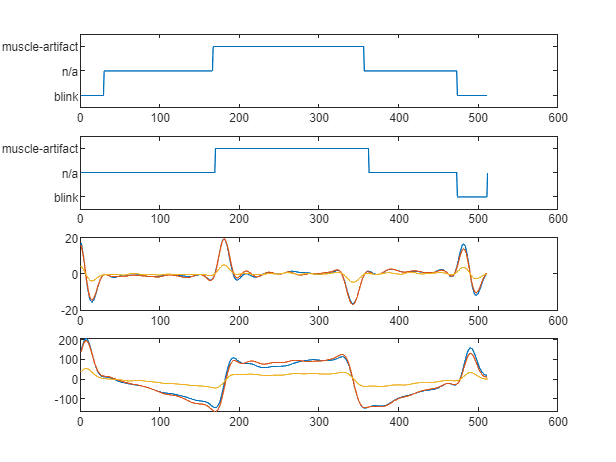

i = 161;
i=errorList(2);
Ypred = YPred{i};
Ytest = YTest{i};
Xtest = XTest{i};
Xdif = diff(Xtest')';

figure;
subplot(4,1,1);plot(Ytest);
subplot(4,1,2);plot(Ypred);
subplot(4,1,3);plot(Xdif');
subplot(4,1,4);plot(Xtest');


blinkLocate(Xtest,Ytest),blinkLocate(Xtest,Ypred)

ans =      7   491


ans = 491


groundTruth = {};
predicted = {};
TP = 0;FP = 0;FN=0;
errorList = [];
for i = 1:numel(Ytest)
    gt = blinkLocate(XTest{i},YTest{i});
    p = blinkLocate(XTest{i},YPred{i});
    groundTruth{end+1} = gt;
    predicted{end+1} = p;
    
    TP = TP + numel(intersect(gt,p));
    if (numel(gt) > numel(p))
        FN = FN + numel(gt) - numel(p);
    else
        FP = FP + numel(p) - numel(gt);
    end
    if (numel(gt) ~= numel(p))
        errorList(end+1) = i;
    end        
end
TP,FP,FN,errorList

TP = 417

FP = 4

FN = 10

errorList =     11   167   172   178   212   230   272   292   293   310   315   333   445


TP/(TP+FP),TP/(TP+FN)

ans = 0.9905

ans = 0.9766